# LineGradient

**Overview**

The `LineGradient` chart manages a line plot which has an associated color gradient. The chart data comprises an increasing `datetime` vector (`XData`) together with a numeric data vector (`YData`). The `YData` is plotted against the `XData` and the color gradient corresponds to the values contained in `YData`. 

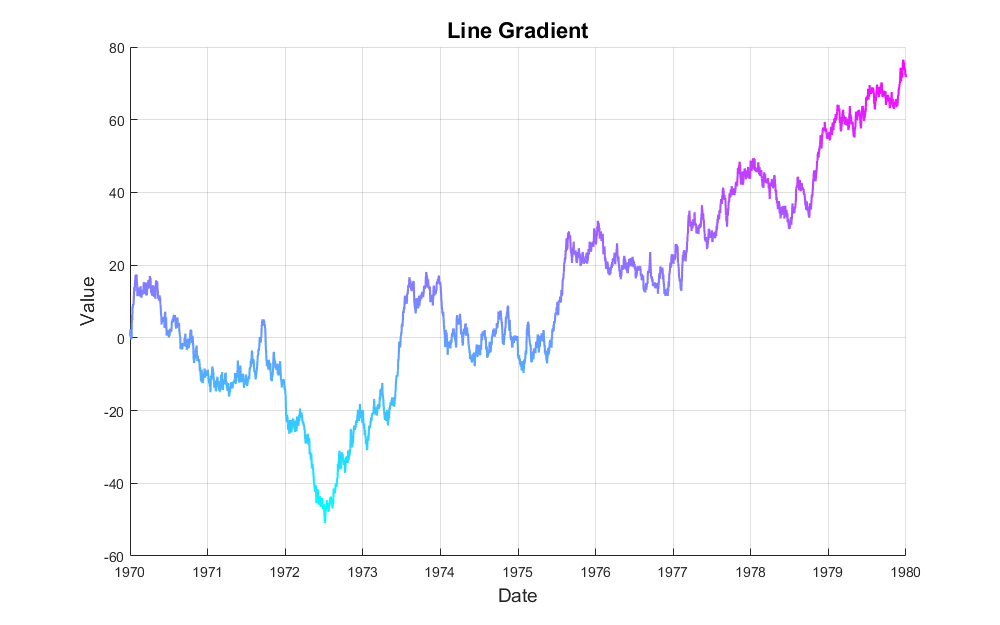

**Resources**

[Open](matlab: edit(fullfile(galleryRoot, '+Examples', 'LineGradient.mlx'))) this Live Script to run and interact with the examples shown below.

[View](matlab: edit(fullfile(galleryRoot, '+Charts', 'LineGradient'))) the source code for the `LineGradient` chart.

Copyright 2018 The MathWorks, Inc.

## Import the chart.

import Charts.LineGradient

## Create data for the chart: dates and a random walk.

dates = datetime( 1970, 1, 1 ) : datetime( 1980, 1, 1 );
rng default
steps = [0, randn( size( dates(1:end-1) ) )];
walk = cumsum( steps );

## Create a figure for the chart.

f = galleryFigure( 'Name', 'LineGradient Example' );

## Create the chart, specifying the data and figure.

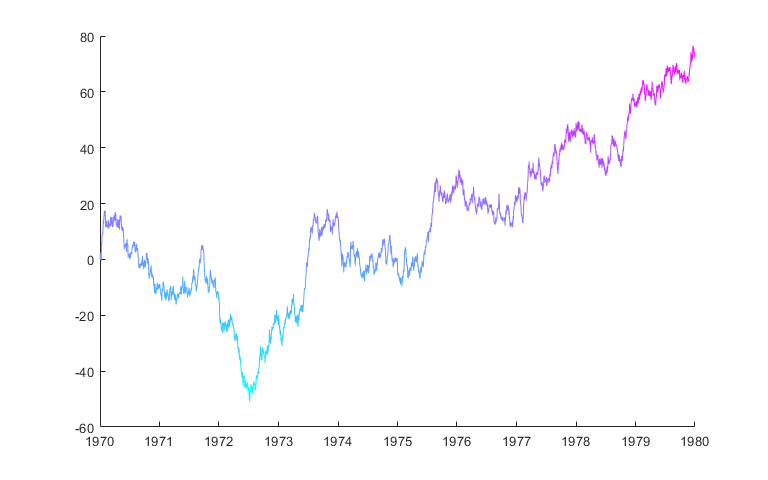

LG = LineGradient( 'Parent', f, ...
                   'XData', dates, ...
                   'YData', walk );

## Annotate the chart and customize its appearance.

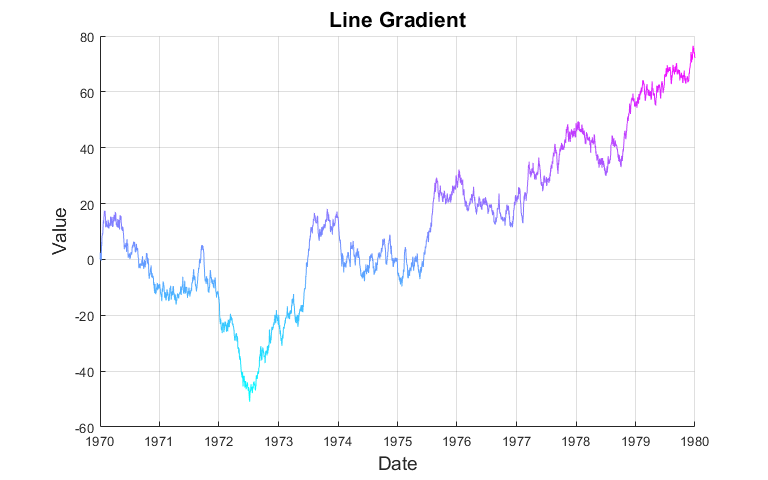

set( LG.XLabel, 'String', 'Date', 'FontSize', 14 )
set( LG.YLabel, 'String', 'Value', 'FontSize', 14 )
set( LG.Title, 'String', 'Line Gradient', 'FontSize', 16 )
LG.Grid = 'on';

## Adjust the width of the line.

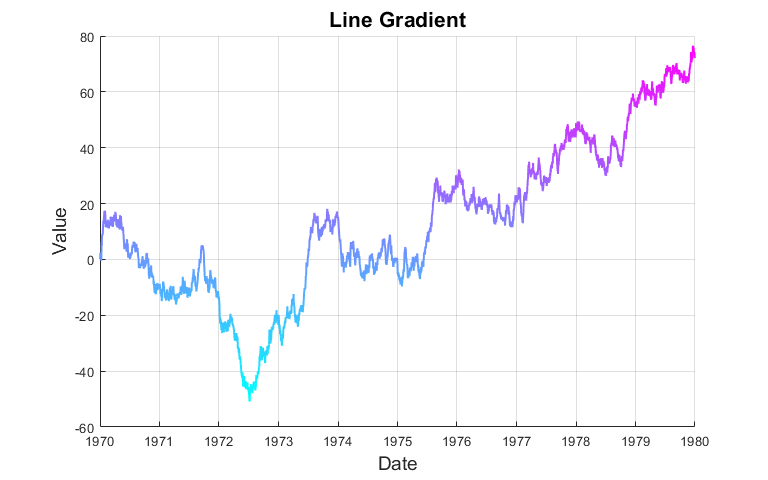

LG.LineWidth = 1.5;

## Change the colormap.

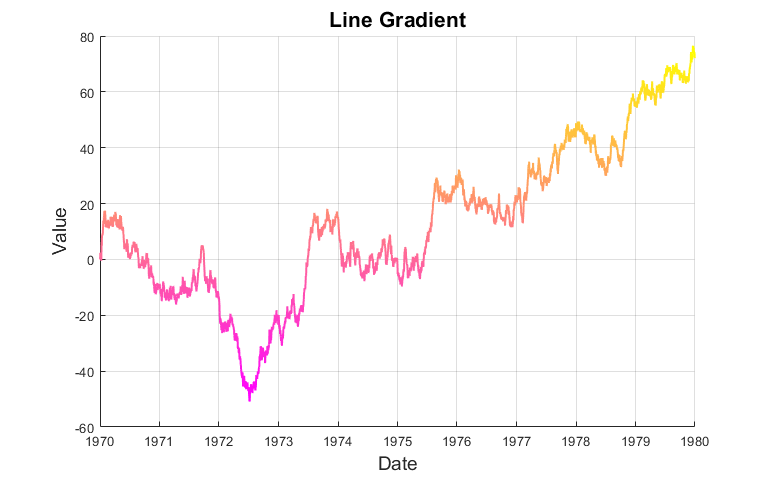

LG.Colormap = spring;

## Change the x-data of the chart to the first 1000 dates.

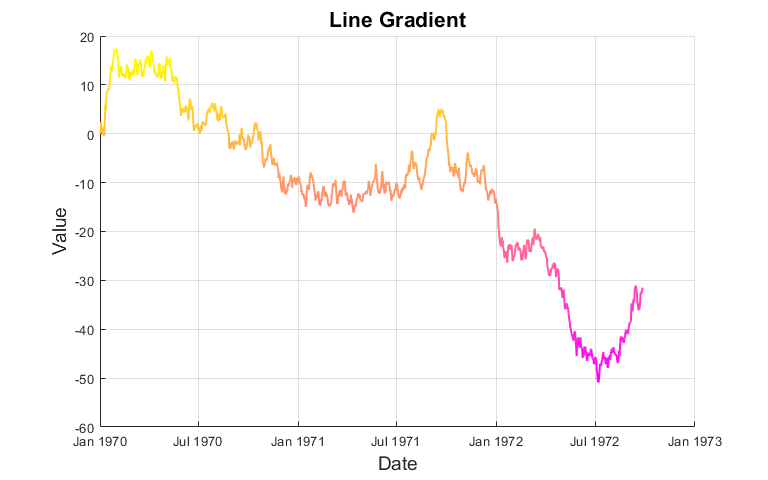

LG.XData = LG.XData(1:1000);

## Change the dates by translating by 10 calendar years.

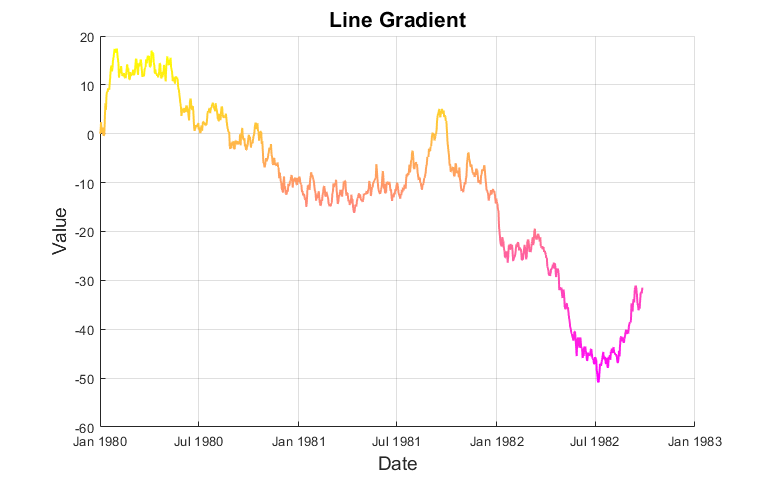

LG.XData = LG.XData + calyears( 10 );

## Change the y-data of the chart to a new random walk.

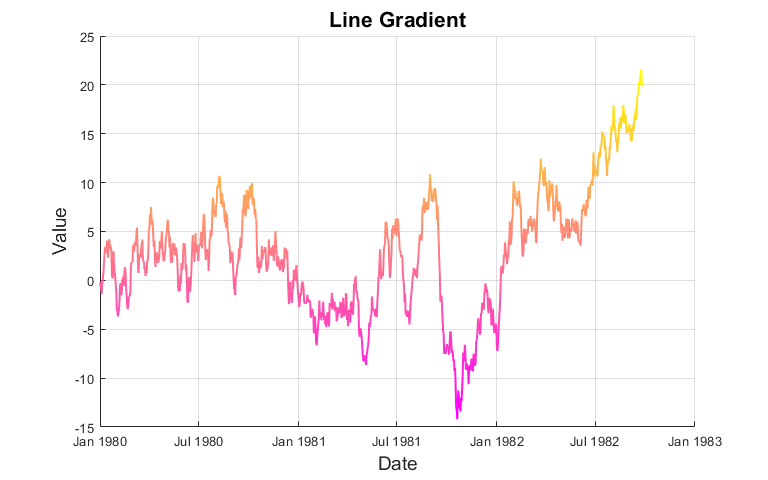

LG.YData = cumsum( randn( size( LG.XData ) ) );